# RGB Image rotation by rotation matrix (manual method)

## 1. read image

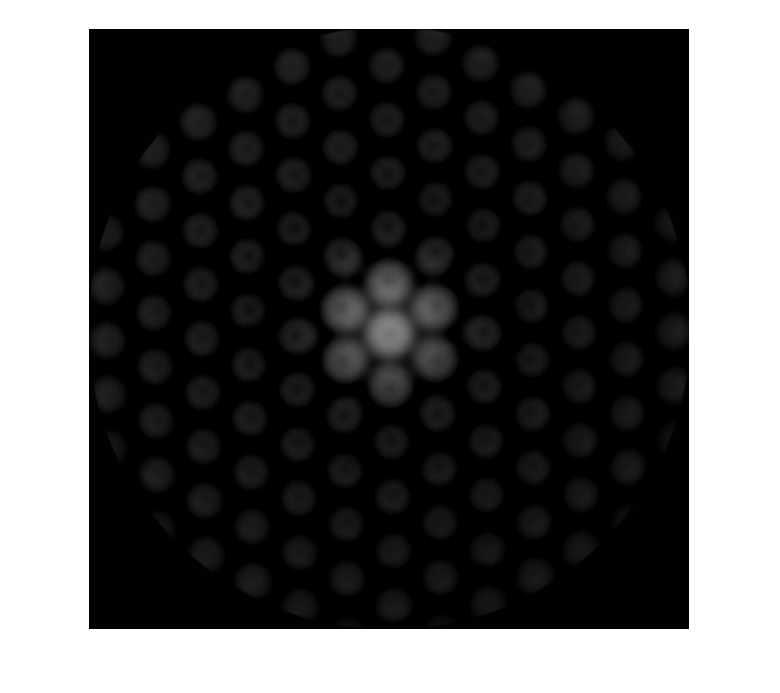

image = imread('class_19.tif');
imshow(image)

## 2. apply rotation matrix to pixel locations

rotate around center of the image

% Convert to radians and create transformation matrix
degree=30;
a = degree*pi/180;
R = [+cos(a) +sin(a); -sin(a) +cos(a)]; % CCW

[nrows, ncols] = size(image);
midx=ceil((ncols+1)/2);
midy=ceil((nrows+1)/2);
% rotate about center
[X, Y] = meshgrid(1:ncols,1:nrows);
XYt = [X(:)-midx Y(:)-midy];
XYt = XYt*Mr;
XYt = XYt + [midx midy];

## 3. Approximate new pixel locations to their nearest neighbor (lossy for color)

xout = round(XYt(:,1)); yout = round(XYt(:,2)); % nearest neighbor!
outbound = yout<1 | yout>nrows | xout<1 | xout>ncols; %mark pixels to be cropped
xout(xout<1) = 1; xout(xout>ncols) = ncols;
yout(yout<1) = 1; yout(yout>nrows) = nrows;

## 4. look up pixel values from original image

This is done efficiently by converting subscripts of rotated coordinates to index imposed by the original image

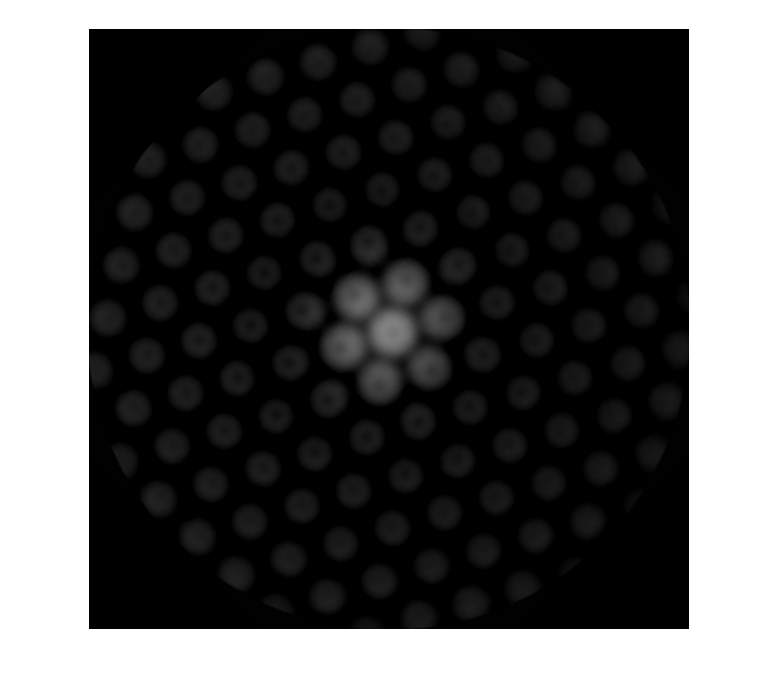

imagerot = image(sub2ind(size(image),yout,xout)); 
imagerot = reshape(imagerot,size(image));
imagerot(outbound) = 0; % set background value to [0 0 0] (black)
imshow(imagerot);